clear all
close all
clc

**3. Variáveis e distribuições aleatórias**

1. Considere a vari´avel aleatória X correspondente a face que fica para cima no lançamento de 1 dado. Usando os valores teoricos: 

(a) Produza um gráfico, em Matlab, que represente a funcao massa de probabilidade1 de X; 

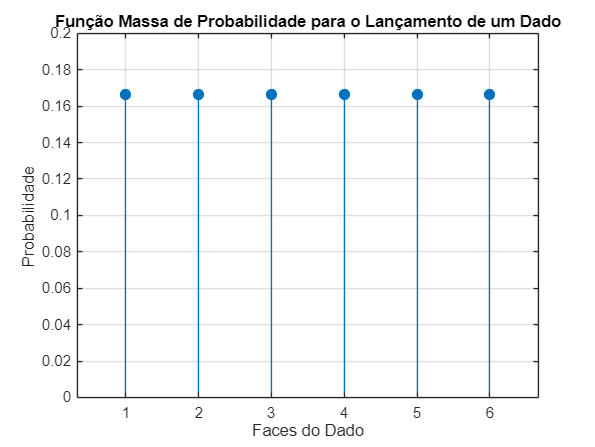

% Valores possíveis para o dado
x = 1:6; % Faces do dado

% Probabilidades para cada face
p = repmat(1/6, 1, 6); % Probabilidade igual para cada face

% Calcular a função de distribuição acumulada (CDF)
F = cumsum(p); % Soma acumulada das probabilidades

% Criar a figura
figure;

% Gráfico da função massa de probabilidade
stem(x, p, 'filled', 'MarkerSize', 7);
xlabel('Faces do Dado');
ylabel('Probabilidade');
title('Função Massa de Probabilidade para o Lançamento de um Dado');
xticks(x);
ylim([0 0.2]);
grid on;

(b) Num segundo grafico da mesma figura, desenhe o grafico da funcao de distribuicão acumulada (use a funcão stairs do Matlab).

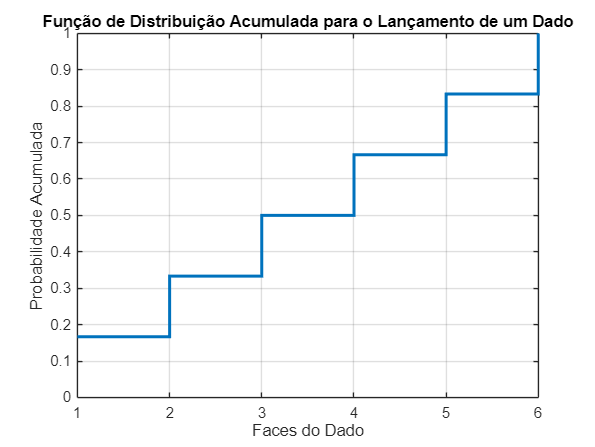

figure;
% Gráfico da função de distribuição acumulada
stairs(x, F, 'LineWidth', 2);
xlabel('Faces do Dado');
ylabel('Probabilidade Acumulada');
title('Função de Distribuição Acumulada para o Lançamento de um Dado');
xticks(x);
ylim([0 1]);
grid on;

2. Considere uma caixa contendo 90 notas de 5 Euros, 9 notas de 50 e 1 de 100. 

(a) Descreva o espaçoo de amostragem da experiencia aleatoria “retirar uma nota da caixa” e as proba bilidades dos acontecimentos elementares. 

S = {5, 50, 100}

S = 1×3 cell array
    {[5]}    {[50]}    {[100]}


P_5 = 90/100

P_5 = 0.9000

P_50 = 9/100

P_50 = 0.0900

P_100 = 1/100

P_100 = 0.0100

(b) Considere agora a variavel aleatoria X como sendo o valor de uma nota retirada à sorte da caixa acima descrita. Descreva o espaço de amostragem e a funcao massa de probabilidade de X. 

Sb = [5, 50, 100]

Sb =      5    50   100


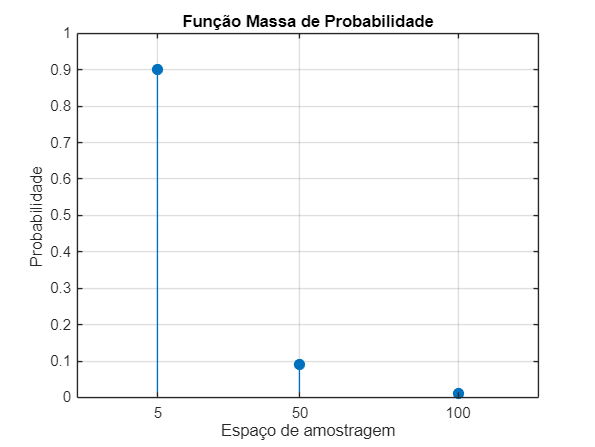

prob = [90/100, 9/100, 1/100];
% Criar a figura
figure;

% Gráfico da função massa de probabilidade
stem(Sb, prob, 'filled', 'MarkerSize', 7);
xlabel('Espaço de amostragem');
ylabel('Probabilidade');
title('Função Massa de Probabilidade');
xticks(Sb);
ylim([0 1]);
grid on;

(c) Determine a funcao de distribuicao acumulada de X, FX(x), e efetue a sua representacao grafica em Matlab.

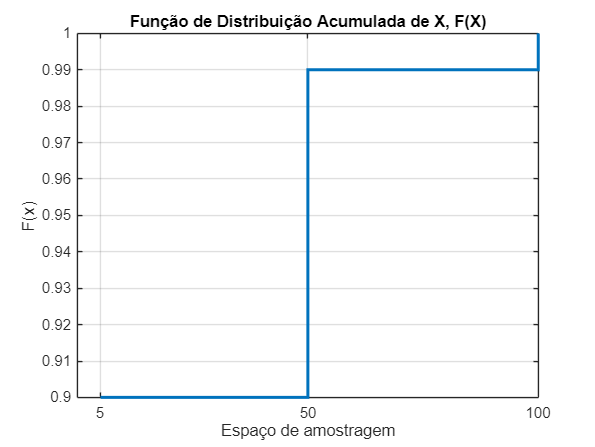

figure;
% Gráfico da função de distribuição acumulada
soma = cumsum(prob);
stairs(Sb, soma, 'LineWidth', 2);
xlabel('Espaço de amostragem');
ylabel('F(x)');
title('Função de Distribuição Acumulada de X, F(X)');
xticks(Sb);
grid on;

 3. Considere 4 lancamentos de uma moeda equilibrada. Seja X a variavel aleatoria representativa do numero de coroas observados nos 4 lancamentos. 

(a) Estime por simulacao a funcao massa de probabilidade pX(x) da variavel aleatoria X. 

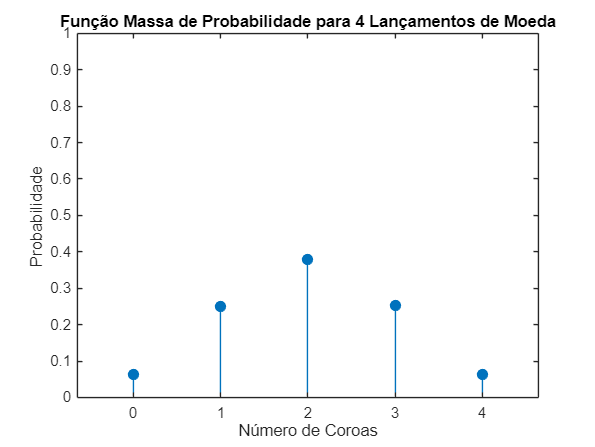

N = 1e5; 
% Espaço amostral para o número de coroas
S = 0:4; 
probs = zeros(1, length(S)); 

for value = S
    cont = 0; % Contador de coroas
    for sim = 1:N
        % Simular 4 lançamentos de uma moeda (1 para coroa, 0 para cara)
        flips = randi([0, 1], 1, 4); % 0 = cara, 1 = coroa
        numCoroas = sum(flips); 
        if numCoroas == value
            cont = cont + 1; 
        end
    end
    % Calcular a probabilidade
    probs(value + 1) = cont / N; 
end

figure;
stem(S, probs, 'filled', 'MarkerSize', 7);
xlabel('Número de Coroas');
ylabel('Probabilidade');
title('Função Massa de Probabilidade para 4 Lançamentos de Moeda');
xticks(S);
ylim([0 1]);

(b) Estime o valor esperado, a variancia e o desvio padrao de X com base em pX(x). 

n = 4;
p = 0.5;
X = 0:n;

pX = binopdf(X, n, p)      % Calcular a distribuição binomial para pX(x)

pX =     0.0625    0.2500    0.3750    0.2500    0.0625



E_X = sum(X .* pX)         % Calcular o valor esperado

E_X = 2


Var_X = sum((X - E_X).^2 .* pX)    % Calcular a variância

Var_X = 1


desvio_padrao_X = sqrt(Var_X)      % Calcular o desvio padrão

desvio_padrao_X = 1

(c) Identifique o tipo da distribuicao da variavel aleatoria X e escreva a expressao teorica da respetiva funcao de probabilidade. 

n = 4;
p = 0.5;
X = 0:n

X =      0     1     2     3     4



pX = binopdf(X, n, p)      % Calcular a função de probabilidade binomial P(X=x)

pX =     0.0625    0.2500    0.3750    0.2500    0.0625


(d) Calcule os valores teoricos da funcao massa de probabilidade de X e compare-os com os valores estimados por simulacao obtidos em (a). 

(e) Calcule os valores teoricos de E[x] e de Var(X) e compare-os com os valores obtidos em (b). 

E_X = 4*0.5

E_X = 2

Var_X = E_X*(1-0.5)

Var_X = 1

(f) Com base nos valores teoricos da funcao massa de probabilidade desta distribuicao, calcule: 

i. a probabilidade de obter pelo menos 2 coroas; 

n = 4;
p = 0.5;
X = 0:1

X =      0     1



pX = binopdf(X, n, p);

prob = 1-sum(pX)

prob = 0.6875

ii. a probabilidade de obter ate 1 coroa; 

sum(pX)

ans = 0.3125

iii. a probabilidade de obter entre 1 e 3 coroas.

n = 4;
p = 0.5;
X = 1:3

X =      1     2     3



pX = binopdf(X, n, p);

prob = sum(pX)

prob = 0.8750

4. Sabendo que um processo de fabrico produz 30% de pecas defeituosas e considerando a variavel aleatoria X, representativa do numero de peças defeituosas numa amostra de 5 pecas tomadas aleatoriamente, obtenha: 

(a) Por simulacao: 

i. estimativa para a funcao massa de probabilidade de X; 

n = 5;              
p = 0.3;           
N = 1e5; 

count_defective = zeros(N, 1);    % vetor para contar o número de peças defeituosas

for i = 1:N

    sample = rand(n, 1) < p;  % Gera um vetor lógico (1 se defeituosa, 0 se não)
    count_defective(i) = sum(sample); % Conta o número de peças defeituosas
end

% Estima a função massa de probabilidade
fmp_estimate = histcounts(count_defective, 'Normalization', 'probability', 'BinMethod', 'integers')

fmp_estimate =     0.1669    0.3600    0.3104    0.1329    0.0273    0.0025


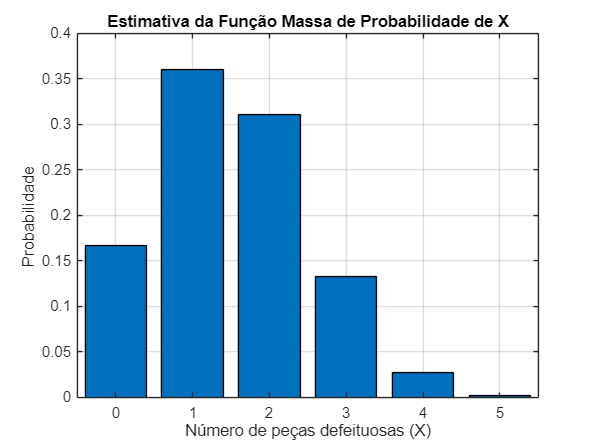


X_values = 0:n;

% Plotar a função massa de probabilidade
figure;
bar(X_values, fmp_estimate);
xlabel('Número de peças defeituosas (X)');
ylabel('Probabilidade');
title('Estimativa da Função Massa de Probabilidade de X');
xlim([-0.5 n + 0.5]);
grid on;

ii. o grafico representativo da funcao distribuicao acumulada de probabilidades de X; 

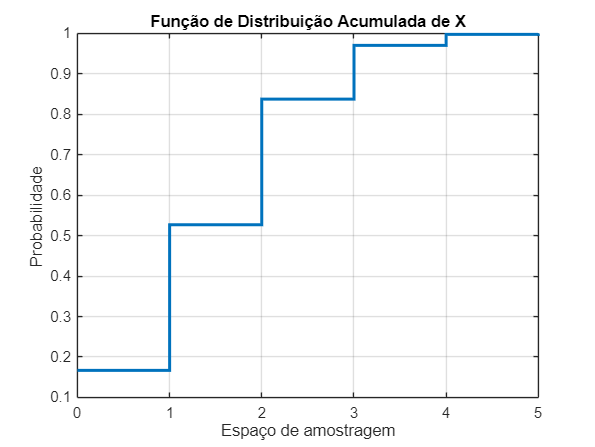

soma = cumsum(fmp_estimate);
stairs(X_values, soma, 'LineWidth', 2);
xlabel('Espaço de amostragem');
ylabel('Probabilidade');
title('Função de Distribuição Acumulada de X');
xticks(X_values);
grid on;

iii. estimativa para probabilidade de, no maximo, 2 das peças de uma amostra serem defeituosas. 

n = 5;              
p = 0.3;           
N = 1e5; 

count = 0;

for i = 1:N

    sample = rand(n, 1) < p;  % Gera um vetor lógico (1 se defeituosa, 0 se não)
    count_defective = sum(sample); % Conta o número de peças defeituosas
    if (count_defective <= 2)
        count = count + 1;
    end
end
prob = count/N

prob = 0.8368

(b) Analiticamente: 

i. a funcao distribuicao acumulada de X; 

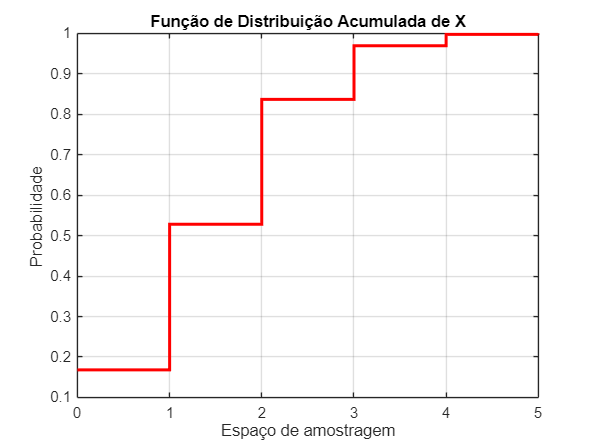

fda_t_X = binocdf(X_values, n, p);
stairs(X_values, fda_t_X, 'LineWidth', 2, 'Color', 'r');
xlabel('Espaço de amostragem');
ylabel('Probabilidade');
title('Função de Distribuição Acumulada de X');
xticks(X_values);
grid on;

ii. a probabilidade de, no maximo, 2 das pecas de uma amostra serem defeituosas.

n = 5;
p = 0.3;
X = 0:2;

pX = binopdf(X, n, p);

prob = sum(pX)

prob = 0.8369

 5. Suponha que o(s) motor(es) de um aviao pode(m) falhar com probabilidade p e que as falhas sao independentes entre motores. Suponha ainda que o aviao se despenha se mais de metade dos motores falharem. Nestas condicoes, prefere voar num aviao com 2 ou 4 motores? Utilize a distribuicao que considerar mais adequada. Sugestao: Tem pelo menos 2 alternativas: 

(1) obter expressoes para a probabilidade de cada tipo de aviao se despenhar em funcao de p e usar o quociente entre ambas para responder a questao,

(2) efectuar os calculos para um conjunto de valores concretos de p (ex: p= logspace(-3,log10(1/2),100)) e usar um grafico mostrando simultaneamente as probabilidades de cada tipo de aviao se despenhar.

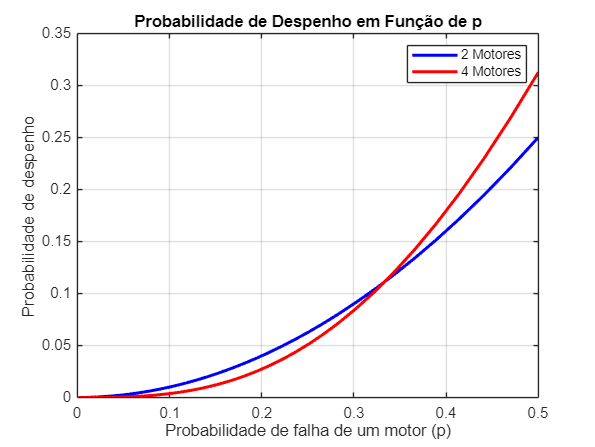

p = logspace(-3, log10(1/2), 100); % Valores de p de 0.001 a 0.5

% Calcular probabilidades de despenho
P_D2 = p.^2; % Para 2 motores
P_D4 = 4*p.^3 - 3*p.^4; % Para 4 motores

% Criar gráfico
figure;
plot(p, P_D2, 'b-', 'LineWidth', 2); % Probabilidade de despenho para 2 motores
hold on;
plot(p, P_D4, 'r-', 'LineWidth', 2); % Probabilidade de despenho para 4 motores
xlabel('Probabilidade de falha de um motor (p)');
ylabel('Probabilidade de despenho');
title('Probabilidade de Despenho em Função de p');
legend('2 Motores', '4 Motores');
grid on;

6. A distribuicao de Poisson e uma forma limite da distribuicao binomial (quando n → ∞ , p → 0 e np permanece constante) e portanto pode ser usada para aproximar e simplificar os calculos envolvidos com a binomial em situacoes em que as condicoes anteriores se verifiquem. Num processo industrial de fabrico de chips, alguns aparecem defeituosos tornando-os inapropriados para comercializacao. E sabido que em media por cada 1000 chips ha um defeituoso. 

(a) Usando a distribuicao binomial, determine a probabilidade de numa amostra de 8000 chips apare cerem 7 defeituosos. 

(b) Determine a mesma probabilidade usando a aproximacao de Poisson e compare o resultado com o da alınea anterior. Lei de Poisson: pk = λk k! e−λ